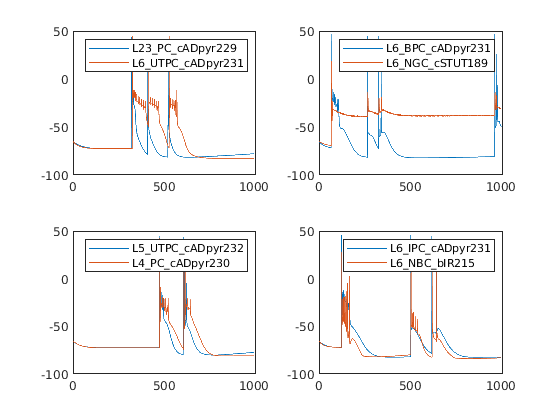

%Plot some sample cell recordings

dataInputDirPath = "../neurpy_git/2cell_outputs2/";

dataFilePaths = dir( dataInputDirPath + "*_probes.csv" );
numFiles = length( dataFilePaths );
dataFilePaths = dataFilePaths( randperm( numFiles ) );
dataFilePaths = dataFilePaths( 1:4 ); %Take 4 measurements

figure();
subplot( 1, 1, 1 );
title( "Comparison of sample spike trains" );
for i = 1:4
    probeFilePath = dataFilePaths( i ).name;
    metaFilePath = strrep( probeFilePath, "_probes.csv", "_meta.json" );
    metaFilePath = strcat( dataInputDirPath, metaFilePath );
    probeFilePath = strcat( dataInputDirPath, probeFilePath );
    probeData = csvread( probeFilePath, 1 );
    
    tVec = probeData( :, 1 );
    headVolt = probeData( :, 2 );
    tailVolt = probeData( :, 3 );
    
    jsonStr = fileread( metaFilePath );
    jsonData = jsondecode( jsonStr );
    preSynStr = jsonData.preSynType;
    postSynStr = jsonData.postSynType;
    cSplit = regexp( preSynStr, "_", 'split' );
    preSynStr = strcat( cSplit( 1, 2 ), "\_", cSplit( 1, 3 ), "\_", cSplit( 1, 1 ) );
    cSplit = regexp( postSynStr, "_", 'split' );
    postSynStr = strcat( cSplit( 1, 2 ), "\_", cSplit( 1, 3 ), "\_", cSplit( 1, 1 ) );
    
    subplot( 2, 2, i );
    xlabel( "Time (ms)" );
    ylabel( "Soma Potential (mV)" );
    
    plot( tVec, headVolt );
    hold on;
    plot( tVec, tailVolt );
    xlim( [ 0 1010 ] );
    legend( preSynStr, postSynStr );
end

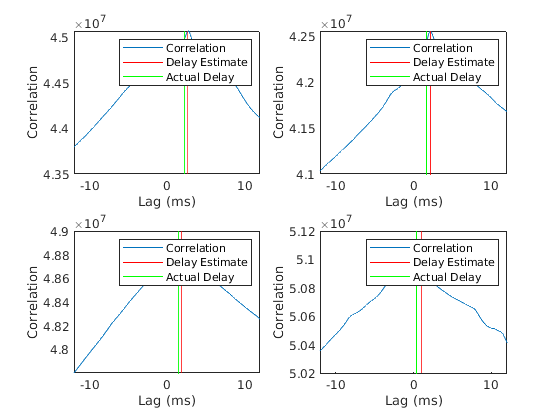

% Plot the delay estimation graphs
dataInputDirPath = "../neurpy_git/2cell_outputs2/";

dataFilePaths = dir( dataInputDirPath + "*_probes.csv" );
numFiles = length( dataFilePaths );
dataFilePaths = dataFilePaths( randperm( numFiles ) );
dataFilePaths = dataFilePaths( 1:4 ); %Take 4 measurements

timeInterval = 0.1;

figure();
for i = 1:4
    probeFilePath = dataFilePaths( i ).name;
    metaFilePath = strrep( probeFilePath, "_probes.csv", "_meta.json" );
    metaFilePath = strcat( dataInputDirPath, metaFilePath );
    probeFilePath = strcat( dataInputDirPath, probeFilePath );
    probeData = csvread( probeFilePath, 1 );
    
    tVec = probeData( :, 1 );
    headVolt = probeData( :, 2 );
    tailVolt = probeData( :, 3 );
    
    % Cross-correlate to estimate delay
    [ sigCorr, lags ] = xcorr( tailVolt, headVolt, 150 );
    % Find local maxima in the correlation
    [ peaks, pkLocs ] = findpeaks( sigCorr, lags, 'MinPeakHeight',1.0 );
    % Try to find the lowest lag value that isn't 0
    pkLocs = pkLocs( pkLocs > 0.0 );
    delayEstTimeSteps = 0;
    if( ~isempty( pkLocs ) )
        delayEstTimeSteps = pkLocs( 1 );
    end
    % Delay estimate in simulation timesteps, convert to MS
    delayEstMs = delayEstTimeSteps * timeInterval;
    lags = lags .* timeInterval;
    
    jsonStr = fileread( metaFilePath );
    jsonData = jsondecode( jsonStr );
    preSynStr = jsonData.preSynType;
    postSynStr = jsonData.postSynType;
    cSplit = regexp( preSynStr, "_", 'split' );
    preSynStr = strcat( cSplit( 1, 2 ), "\_", cSplit( 1, 3 ), "\_", cSplit( 1, 1 ) );
    cSplit = regexp( postSynStr, "_", 'split' );
    postSynStr = strcat( cSplit( 1, 2 ), "\_", cSplit( 1, 3 ), "\_", cSplit( 1, 1 ) );
    actualDelay = jsonData.edgeDelay;
    
    
    
    hax = subplot( 2, 2, i );

    
    plot( lags, sigCorr );
    hold on;
    xlim( [ -12 12 ] );
    plotYlims = get(hax,'YLim');
    lineYs = [ 0 1e8 ];
    
    SP=delayEstMs;   
    line([SP SP],lineYs,'Color',[1 0 0]);
    SP = actualDelay;
    line([SP SP],lineYs,'Color',[0 1 0]);
    
    legend( "Correlation", "Delay Estimate", "Actual Delay" );
    xlabel( "Lag (ms)" );
    ylabel( "Correlation" );
    ylim( plotYlims );
end

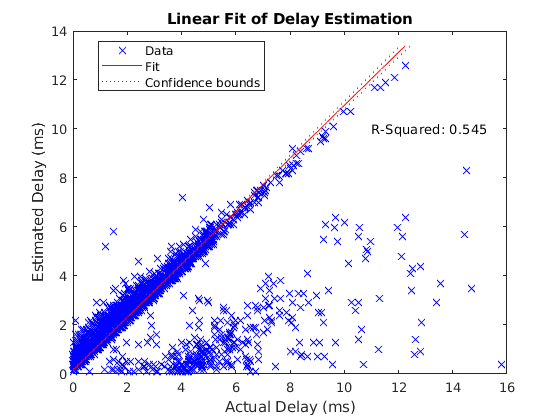

% Plot the Delay-esimate correlation graph. Needs "analyseDelay" to be run first

estimates = delayDataTable.EstimatedDelay;
actuals = delayDataTable.ActualDelay;

actuals = actuals( estimates > 0);
estimates = estimates( estimates > 0);
mdl = fitlm( estimates, actuals );
rScore = mdl.Rsquared.Ordinary;
rScoreText = sprintf( "R-Squared: %02.3f", rScore );
figure();
plot( mdl );

text( 10, 11, rScoreText );
xlabel( "Estimated Delay (ms)" );
ylabel( "Actual Delay (ms)" );
title( "Linear Fit of Delay Estimation" );
view([90 -90]);
ylim( [ 0 16 ] );

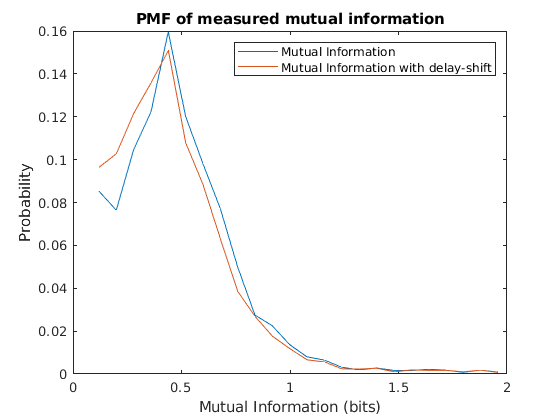

% Plot the information theory data.
mInfo = outputDataTable.MutualInfo;
mInfoShft = outputDataTable.MutualInfoShifted;
entropy = outputDataTable.Entropy_PostSyn;

[ pmfMInfo, XmInfo ] = hist( mInfo, 24 );
[ pmfMInfoShft, XmInfoShft ] = hist( mInfoShft, 24 );
[ pmfEntropy, Xentropy ] = hist( entropy, 11 );

pmfMInfo = pmfMInfo / length( mInfo );
pmfMInfoShft = pmfMInfoShft / length( mInfoShft );
pmfEntropy = pmfEntropy / length( entropy );


figure();
plot( XmInfo, pmfMInfo );
hold on;
plot( XmInfoShft, pmfMInfoShft );
title( "PMF of measured mutual information" );
xlabel( "Mutual Information (bits)" );
ylabel( "Probability" );
legend( "Mutual Information", "Mutual Information with delay-shift" )

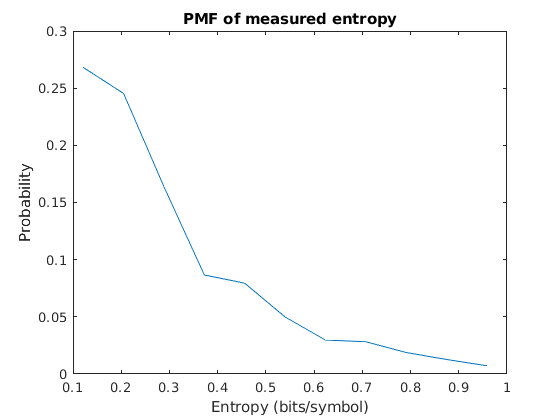


figure();
plot( Xentropy, pmfEntropy );
title( "PMF of measured entropy" );
xlabel( "Entropy (bits/symbol)" );
ylabel( "Probability" );

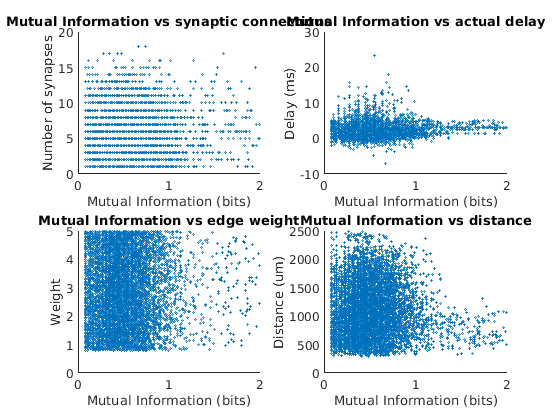

% Plot scatter graphs of mutual info vs edge parameters
connCount = outputDataTable.connCount;
delay = outputDataTable.delay;
weight = outputDataTable.weight;
distance = outputDataTable.distance;
mInfo = outputDataTable.MutualInfo;

figure();
subplot( 2, 2, 1 );
scatter( mInfo, connCount, 1 );
title( "Mutual Information vs synaptic connections" );
xlabel( "Mutual Information (bits)" );
ylabel( "Number of synapses" );

subplot( 2, 2, 2 );
scatter( mInfo, delay, 1 );
title( "Mutual Information vs actual delay" );
xlabel( "Mutual Information (bits)" );
ylabel( "Delay (ms)" );

subplot( 2, 2, 3 );
scatter( mInfo, weight, 1 );
title( "Mutual Information vs edge weight" );
xlabel( "Mutual Information (bits)" );
ylabel( "Weight" );

subplot( 2, 2, 4 );
scatter( mInfo, distance, 1 );
title( "Mutual Information vs distance" );
xlabel( "Mutual Information (bits)" );
ylabel( "Distance (um)" );

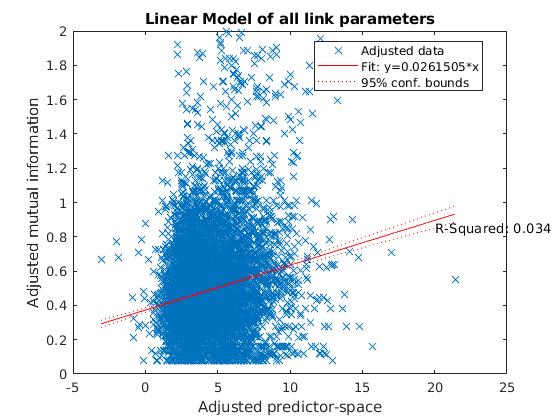

% Run anova analysis on the mutual information and edge-params
connCount = outputDataTable.connCount;
delay = outputDataTable.delay;
weight = outputDataTable.weight;
distance = outputDataTable.distance;
mInfo = outputDataTable.MutualInfo;

tdata = mInfo( ~any( isnan( mInfo ) | isinf( mInfo ), 2 ),: );


factors = [ connCount, delay, weight, distance ];
factors = factors( ~any( isnan( mInfo ) | isinf( mInfo ), 2 ),: );
mInfo = mInfo( ~any( isnan( mInfo ) | isinf( mInfo ), 2 ),: );
mdl = fitlm( factors, mInfo );
rScore = mdl.Rsquared.Ordinary;
rScoreText = sprintf( "R-Squared: %02.3f", rScore );

figure();
plot( mdl );
ylabel( "Adjusted mutual information" );
xlabel( "Adjusted predictor-space" );
title( "Linear Model of all link parameters" );
text( 20, 0.85, rScoreText );

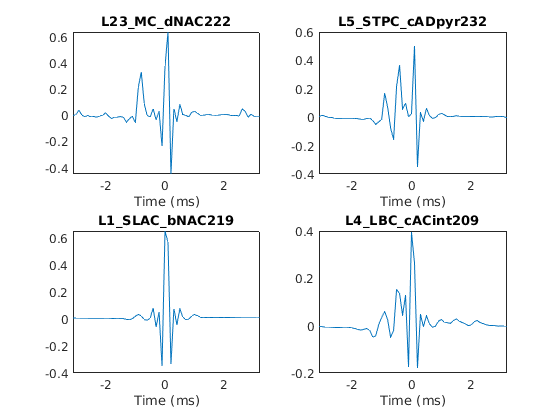

%Plot some sample impulse response plots
trainingData = data;
numObs = height( trainingData );
shuffledData = trainingData( randperm( numObs ), : );
shuffledData = shuffledData( 1:4, : );
figure();
subplot( 1, 1, 1 );
title( "Comparison of sample filter coefficients" );
for i = 1:4
    kFilt = shuffledData( i, 2:65 );
    layer = shuffledData( i, : ).layer;
    mType = shuffledData( i, : ).mtype;
    eType = shuffledData( i, : ).etype;
    cellStr = strcat( layer, "\_", mType, "\_", eType );
    xIdx = -31 : 1 : 32;
    xIdx = xIdx .* 0.1;
    subplot( 2, 2, i );
    kFilt = table2array( kFilt );
    kFilt = [ kFilt( 1, 33:64 ), kFilt( 1, 1:32 ) ];
    plot( xIdx, kFilt );
    title( cellStr );
    xlabel( "Time (ms)" );
    
end

% Reconstruct topology of some random network.
dataInputDirPath = "../neurpy_git/4leaf_outputs_force2/";
dataOutputPath = "./output_kFilt_allSyn.csv";
trainedModelPath = "./cubicSvm64k.mat";

dataFilePaths = dir( dataInputDirPath + "*_probes.csv" );

numFiles = length( dataFilePaths );

dataFilePaths = dataFilePaths( randperm( numFiles ) );

outputDataCell = cell( numFiles + 1, 3 );
outputDataCell( 1, : ) = { 'Prediction' 'Actual' 'Metrics' };

models = load( trainedModelPath );

file = dataFilePaths( 1 );
fileName = file.name;
probeFilePath = strcat( file.folder, strcat( "/", file.name ) );
jsonFilePath = strrep( probeFilePath, "_probes.csv", "_meta.json" );
jsonStr = fileread( jsonFilePath );
jsonData = jsondecode( jsonStr );

probeData = csvread( probeFilePath, 1 );
dataCentralNode = probeData( :, 2 );
estSat1 = predictCell( dataCentralNode, probeData( :, 3 ), models, 64 );
estSat2 = predictCell( dataCentralNode, probeData( :, 4 ), models, 64 );
estSat3 = predictCell( dataCentralNode, probeData( :, 5 ), models, 64 );
estSat4 = predictCell( dataCentralNode, probeData( :, 6 ), models, 64 );
networkPrediction = { estSat1, estSat2, estSat3,...    
                      estSat4 };
joinCellStr = @( gList ) strcat( gList( 1, 1 ), '_', gList( 1, 2 ), '_', gList( 1, 3 ) );

networkActual = { splitCellType( jsonData.leaf1Type ),...
                  splitCellType( jsonData.leaf2Type ),...
                  splitCellType( jsonData.leaf3Type ),...
                  splitCellType( jsonData.leaf4Type ) };

for idx = 1:4
    actCell = networkActual( 1, idx );
    actCell = actCell{:};
    actCell = joinCellStr( actCell );
    
    predCell = networkPrediction( 1, idx );
    predCell = predCell{:};
    predCell = joinCellStr( predCell );
    fprintf( "%s->%s\n", actCell{:}, predCell{:} );
end

L4_cADpyr230_SS->L4_cADpyr230_SS
L23_cIR216_NBC->L23_cACint209_NBC
L1_cNAC187_DAC->L23_cNAC187_NBC
L6_cADpyr231_UTPC->L6_cADpyr231_TPC


function cellTypeCell = splitCellType( cellStr )
    cSplit = regexp( cellStr, "_", 'split' );
    layer = char( cSplit( 1, 2 ) );
    mType = char( cSplit( 1, 1 ) );
    eType = char( cSplit( 1, 3 ) );
    cellTypeCell = { layer, mType, eType };
end